# Introduction to Data Fitting in MATLAB Using Least Squares Regression

This section covers the basics of fitting data using least squares regression in MATLAB. The discussion begins with a simple least squares example, then it generalizes the solution, derives the least squares regression using linear algebra, and finally, demonstrates how to use the ``curve_fit`` function from the SciPy library in Python (using MATLAB's `Python interface`).

## **Background **

In many scientific and engineering disciplines, it is common to encounter experimental data that is adversely affected by `measurement errors`, also known as `noise`. When analyzing such data, it is often desirable to `find a mathematical model` that best `represents` (or fits) the `underlying trend or relationship`. One popular approach to achieve this is through the method of **least squares**, which provides an estimator of the model response to any possible input to the actual system.

The **least squares** approach **minimizes** the **sum of the squared differences** between the **observed** data points and the corresponding values **predicted** by the model, also known as the **residuals**. By minimizing the residuals, we obtain the best-fit parameters that characterize the model.

**Least Squares Example**

To illustrate the concept, let's consider the example of a spring-based weight measuring system. The position of the spring (representing the weight) is measured, but it is influenced by noise from the suspension system. We want to approximate the relationship between the position of the spring and the actual weight.

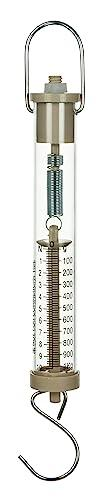

The relationship between the weight and the position of the spring can be approximated by a linear equation of the form:


$$$$
y = k \cdot x + b,
$$$$


where `y` is the position of the spring extended by the weight ***x***,  ***k*** is the unknown stiffness of the spring, and ***b ***is the unknown bias of the spring setting. The goal is to find an explicit relation between the actual weight ***x*** and the "marker" to be placed at ***y***; the experimental process producing this "mapping data" is often called the **calibration**.

Given a set of experimental data point-pairs $(x_i, y_i)$ of length ***n***, our goal is to find the values of ***k*** and ***b*** that minimize the sum of squared residuals across all ***n*** experimental pairs of $(x_i, y_i)$: $E = \sum_{i=1}^{n} (y_i - (k \cdot x_i + b))^2$

The least squares solution can be obtained using different approaches: `linear algebra` and `calculus`. Using **multivariable calculus**, we differentiate the sum of squared residuals *E* with respect to the unknowns ***k*** and ***b***, and set the derivatives to zero: $\frac{\partial E}{\partial b} = 0, \frac{\partial E}{\partial k} = 0$. Solving this system of partial derivative equations will yield the values of ***k*** and ***b***. The equations for the least squares solution are:


$$k = \frac{n (\sum{x_i y_i}) - (\sum{x_i})(\sum{y_i})}{n(\sum{x_i^2}) - (\sum{x_i})^2} \\
b = \frac{(\sum{y_i}) - k(\sum{x_i})}{n}$$


Try deriving those equations using Symbolic toolbox. Tip, start with $i=1$ and then solve the partial derivatives $\frac{\partial E}{\partial b} = 0, \frac{\partial E}{\partial k} = 0$ first for the *b*-equation. Generalize to the case of multiple measurements.

This approach provides a straightforward way to determine the best-fit parameters for a linear model given experimental data.

Lets demostrate this approach in the form we just presented; these are the guts of the algorthm provided by MATLAB.

## Example of Least Squares in "`polyfit()`"

The least squares method aims to minimize the `sum of the squared residuals`, which are the differences between the observed and predicted values.

As previously mentioned, it is a fundamental technique in regression analysis. MATLAB offers a variety of tools and functions that utilize this least squares principle in different ways. While these methods may have varying use cases, the underlying concept of minimizing the mean squared error (`MSE`) remains consistent across implementations.

### Example 4: Polyfit - the right order of the approximting polynomial

% Experimental sampling and data
x = [1, 2, 3, 4, 5];
y = [2.1, 2.9, 3.8, 5.9, 7.3];

% get coefficients of the polynomial and its metrics which "fit" the experimental data
[p,S,mu] = polyfit(x, y, 1); % Fit a first-degree polynomial (line)
y_fit = polyval(p, x,[], mu);
[p2,S2,mu2] = polyfit(x, y, 2); % Fit a second-degree polynomial (quadratic)
y_fit2 = polyval(p2, x,[], mu2);
[p3,S3,mu3] = polyfit(x, y, 3); % Fit a third-degree polynomial (cubic)
y_fit3 = polyval(p3, x,[], mu3);
[p6,S6,mu6] = polyfit(x, y, 6); % Fit a 6th-degree polynomial
y_fit6 = polyval(p6, x,[], mu6);

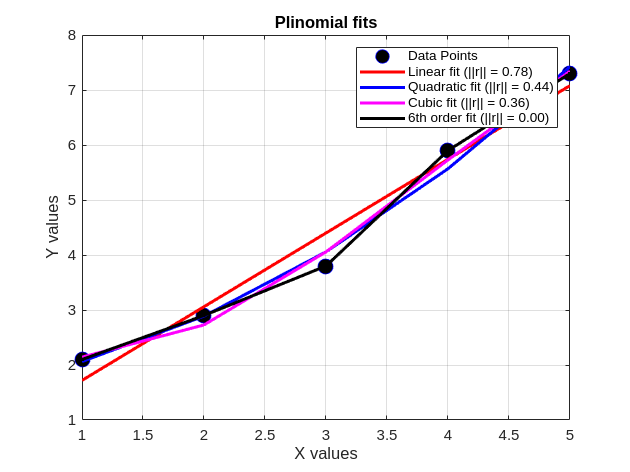


% Plotting the results
figure;
% use 'DisplayName', 'user_defined_name' instead of filling in names in legend()
plot(x, y, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'k', 'DisplayName', 'Data Points');
hold on;
% Y-data reflects metrics of the polynimial
plot(x, y_fit, 'r-', 'LineWidth', 2, 'DisplayName', sprintf('Linear fit (||r|| = %.2f)', S.normr));
plot(x, y_fit2, 'b-', 'LineWidth', 2, 'DisplayName', sprintf('Quadratic fit (||r|| = %.2f)', S2.normr));
plot(x, y_fit3, 'm-', 'LineWidth', 2, 'DisplayName', sprintf('Cubic fit (||r|| = %.2f)', S3.normr));
plot(x, y_fit6, 'k.-', 'LineWidth', 2, 'DisplayName', sprintf('6th order fit (||r|| = %.2f)', S6.normr));

xlabel('X values');
ylabel('Y values');
title('Plinomial fits');
legend show; % now you just have to call "empty" legend to populate the names
grid on; hold off;

Increasing the order of a polynomial fit arbitrarily, especially beyond what is necessary to capture the true trend in data, can lead to a phenomenon known as **overfitting**. Overfitting occurs when a model fits the noise or random fluctuations in the data rather than the underlying trend.

**Consequence**: A higher-order polynomial may pass through or very close to all data points, capturing random variations (noise) rather than the true relationship between variables. This results in a model that performs well on the current data set but poorly on new, unseen data.cu

### Example 1.A: Weight measuring system - Calculus approach

% Experimental data as single precision
x = [1, 2, 3, 4, 5, 6, 7]; % Weight
y = [3.5, 5.6, 5.2, 8.9, 8.1, 13.0, 20.0]; % Position of the spring

% Calculate the least squares solution => compare with the formula above
n = length(x);
k = (n * sum(x .* y) - sum(x) * sum(y)) / (n * sum(x.^2) - (sum(x))^2);
b = (sum(y) - k * sum(x)) / n;
fprintf('Linear regression coefficients: k = %f, b = %f\n', k, b);
% Calculate the relative residual, i.e. normalizes MSE => compare with the formula above

Linear regression coefficients: k = 2.400000, b = -0.414286


E = sum((y - (k * x + b)).^2) / norm(y);
fprintf('Relative residual E = %f\n', E);
% Generate the best-fit line

Relative residual E = 1.162101


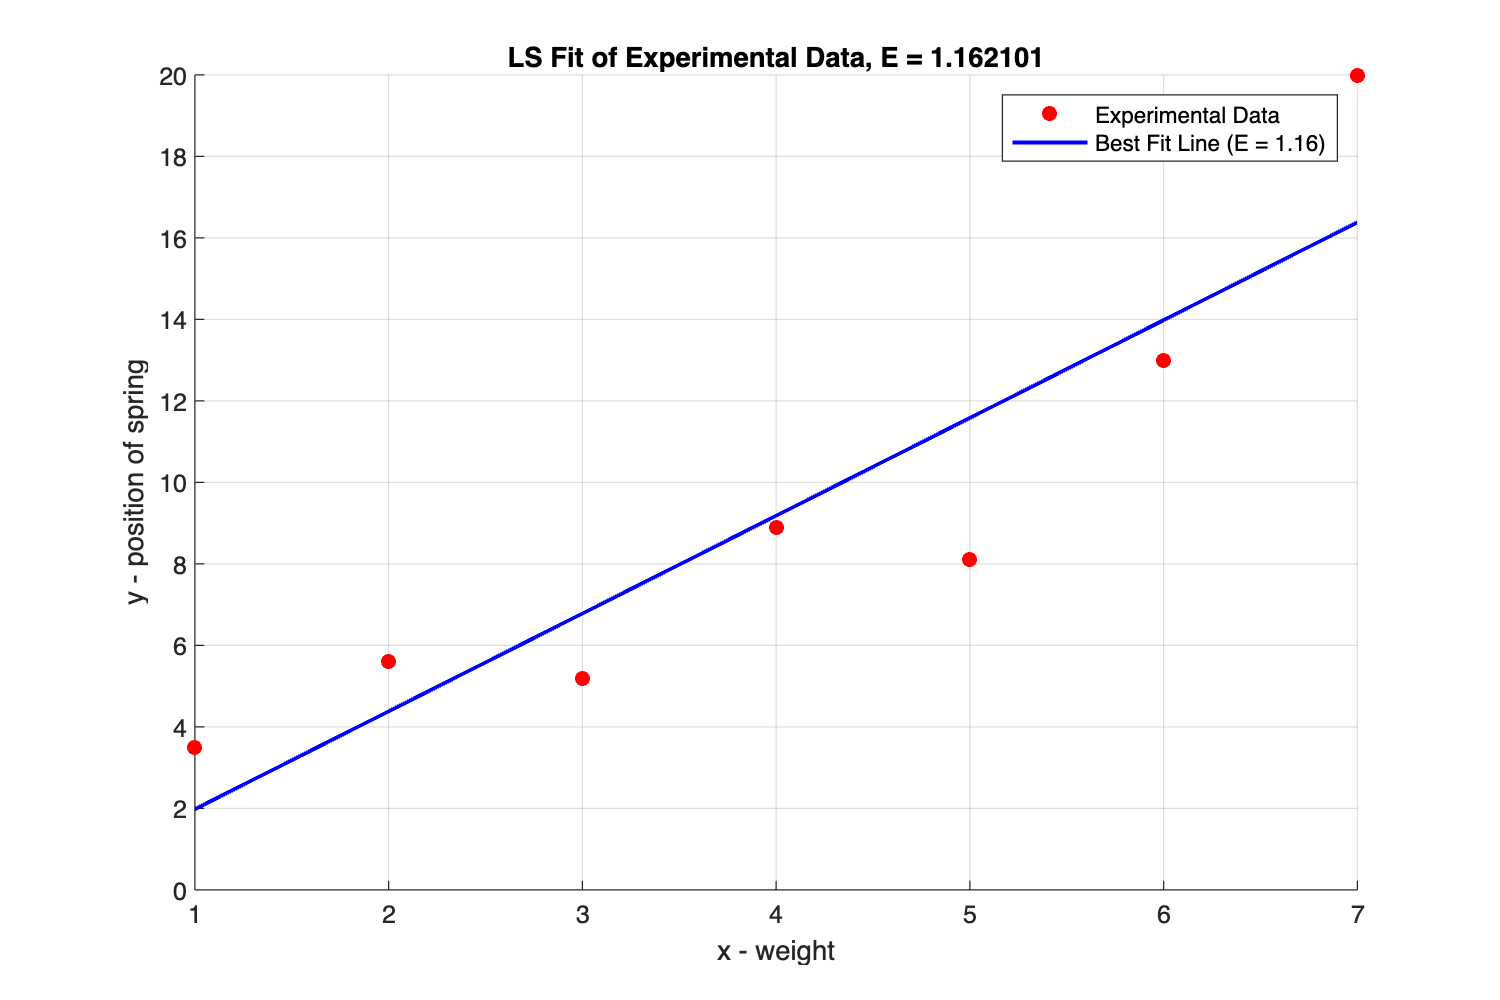

x_fit = linspace(min(x), max(x), 100);
y_fit = k * x_fit + b;

% Plot the experimental data and the best-fit line
figure('Position', [100, 100, 600, 400]);
scatter(x, y, 'r', 'filled', 'DisplayName', 'Experimental Data');
hold on;
plot(x_fit, y_fit, 'b', 'LineWidth', 1.5, 'DisplayName', sprintf('Best Fit Line (E = %.2f)', E));
xlabel('x - weight');
ylabel('y - position of spring');
title(sprintf('LS Fit of Experimental Data, E = %f', E));
legend show;
grid on;
hold off;

## Linear Algebra Approach

Once again, we want to find an estimation function, $$\hat y(x)$$, that describes the relationship between the force and displacement of a linear spring. The estimation function must be a linear combination of `n` basis functions, $ $f_i(x)$$; the meaning and the utility of the basis functio is the same as we discussed inthe `Lagrange` polynomial approach. With respect to a single data point `x` the estimation function has the following form $$\hat y(x) = \alpha_1 * f_1(x) + \alpha_2 * f_2(x) + ... + \alpha_n * f_n(x)$$; where $$\alpha_i$$ are `unknown` coefficients. Let us further assume that the experiment produces `m` measurements (the actual data points $$y_i$$), and the number of measurements $$m \gg n $$. As a result, we shall have `m` estimates of a "true" value; it's worth noting that the "`true`" value is never achievable.


$$\hat{y}(x_1) = {\alpha}_1 f_1(x_1) + {\alpha}_2 f_2(x_1) + \cdots + {\alpha}_n f_n(x_1), \\
\hat{y}(x_2) = {\alpha}_1 f_1(x_2) + {\alpha}_2 f_2(x_2) + \cdots + {\alpha}_n f_n(x_2), \\
\qquad\qquad \qquad \qquad \quad \cdots\\
\hat{y}(x_m) = {\alpha}_1 f_1(x_m) + {\alpha}_2 f_2(x_m) + \cdots + {\alpha}_n f_n(x_m)

$$


Let us introduce vector-matrix notations that significantly shorten the system above:

-  $$X\in R^n$$ is a column vector such that the `i`-th element of *X* contains the $$x_i$$: the column vector of `data points`

-  $$\hat{Y}~$$  is a column vector with elements, $$\hat{Y}_i = \hat{y}(x_i)$$: the column vector of `estimates`

- $${\alpha}$$ is a column vector comprised of $$\alpha_i$$; the column vector of `unknown regressor coefficients`

- $$F_i(x)$$ is a function that returns a column vector of $$f_i(x)$$ computed on every element $$x_i$$;

- `A` be an $$m \times n$$ matrix such that the *i*-th column of *A* is $$F_i(x)$$.

Using this notation, the previous system of equations becomes $$\hat{Y} = A{\alpha}$$ and the rest of calculations significantly shortens. The total squared error is now given by $$E = \|{\hat{Y} - Y}\|_{2}^2$$; this follows from the definition of the $$L_2$$ norm. Since the objective is to minimize *E*, the previous expression is equivalent to saying that we want $$\hat{Y}$$ and *Y* to be as "close as possible." Note that in general *Y* will not be in the space of *A* and therefore $$E > 0$$.

Consider the following simplified depiction of the space of *A*; see the following figure.

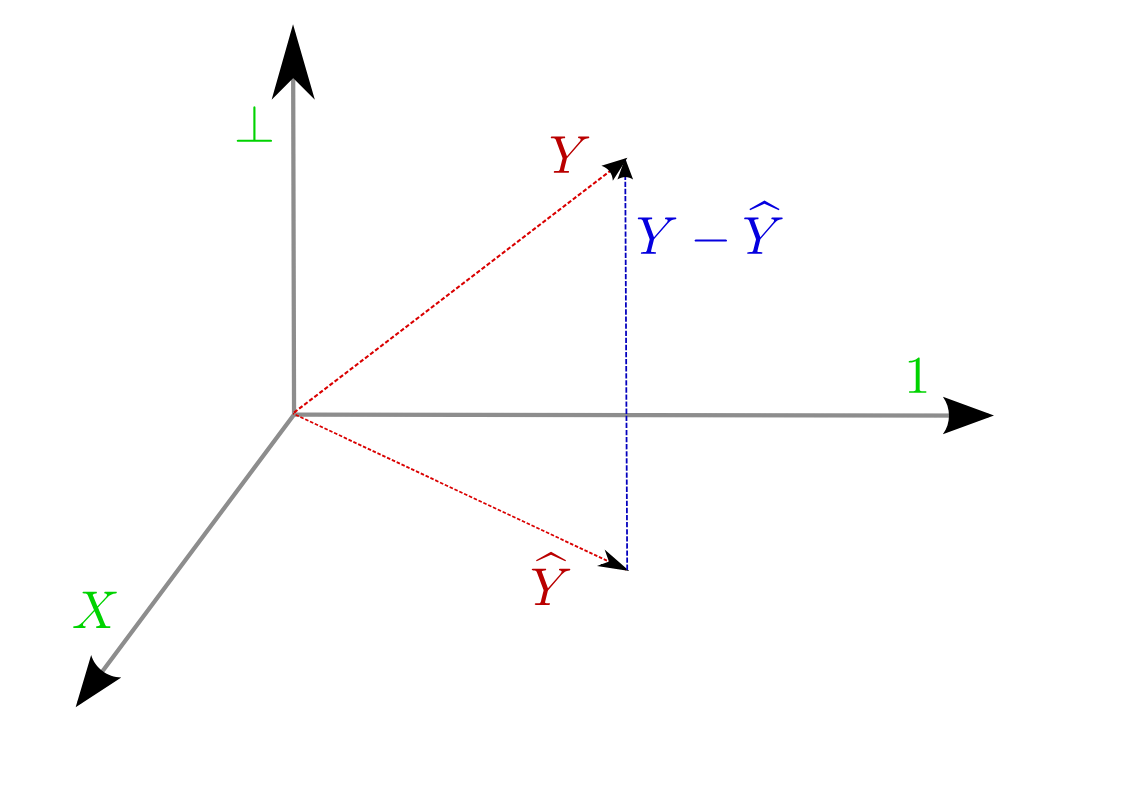

From observation, the vector in the range of $$A, \hat{Y}$$- that is closest to *Y* is the one that can point perpendicularly to *Y*. Therefore, we want a vector $$Y - \hat{Y}$$ that is perpendicular to the vector $$\hat{Y}$$.

We know from `linear algebra` that two vectors are `perpendicular`, or `normal`, if their ``dot`` product is ``0``. The dot product of two vectors, ***u*** and ***v***, can be written as $${\text{dot}}(u,v) = u^T v$$, we can state that $$\hat{Y}$$ and $$Y - \hat{Y}$$ are perpendicular if $${\text{dot}}(\hat{Y}, Y - \hat{Y}) = 0$$; therefore, $$\hat{Y}^T (Y - \hat{Y}) = 0$$, which is equivalent to $$(A{\alpha})^T(Y - A{\alpha}) = 0$$.

Noting that for two matrices ***A*** and ***B***, $(AB)^T = B^T A^T$ and using distributive properties of vector multiplication, this is equivalent to $${\alpha}^T A^T Y - {\alpha}^T A^T A {\alpha} = {\alpha}^T(A^T Y - A^T A {\alpha}) = 0$$. The solution, $${\alpha} = \textbf{0}$$, is a trivial solution, so we use $$A^T Y - A^T A {\alpha} = 0$$ to find a more general solution. Solving this equation for $${\alpha}$$ gives the `least squares regression formula`:


$${\alpha} = (A^T A)^{-1} A^T Y
$$


The $$(A^T A)^{-1}A^T$$ is called the `pseudo-inverse` of *A* and it exists when $$m > n$$ and *A* has linearly independent columns; recal the requirement of the linearly independent basis functions.

### Example 1.B: Weight measuring system - Linear Algebra approach

% Experimental data - use the same set
% x = [1, 2, 3, 4, 5, 6, 7]; % Weight
% y = [3.5, 5.6, 5.2, 8.9, 8.1, 13.0, 20.0]; % Position of the spring


% Step 1: Construct matrix A by stacking x and a column of 1's (x^0 = 1)
% I.e. y = a*x+b*1 , where [a, b] are unknown regressors, and A=[x, 1]
A = [x(:), ones(length(x), 1)]; % A is a matrix with x values in the first column and 1s in the second

% Step 2: Reshape y into a column vector
y = y(:);


Linear regressor coefficients (direct): 2.4    -0.41429


% Option A: Direct Least Squares Regression using normal equations
alpha_direct = (A' * A) \ (A' * y); % Using MATLAB's backslash operator to solve the system
disp(['Linear regressor coefficients (direct): ', num2str(alpha_direct')]);


Linear regressor coefficients (pseudo-inverse): 2.4    -0.41429


% Option B: Using Pseudo-Inverse => not quaranteed to exist
alpha_pinv = pinv(A) * y; % MATLAB's pseudo-inverse function
disp(['Linear regressor coefficients (pseudo-inverse): ', num2str(alpha_pinv')]);

Linear regressor coefficients (using MATLAB LSQ): 2.4    -0.41429


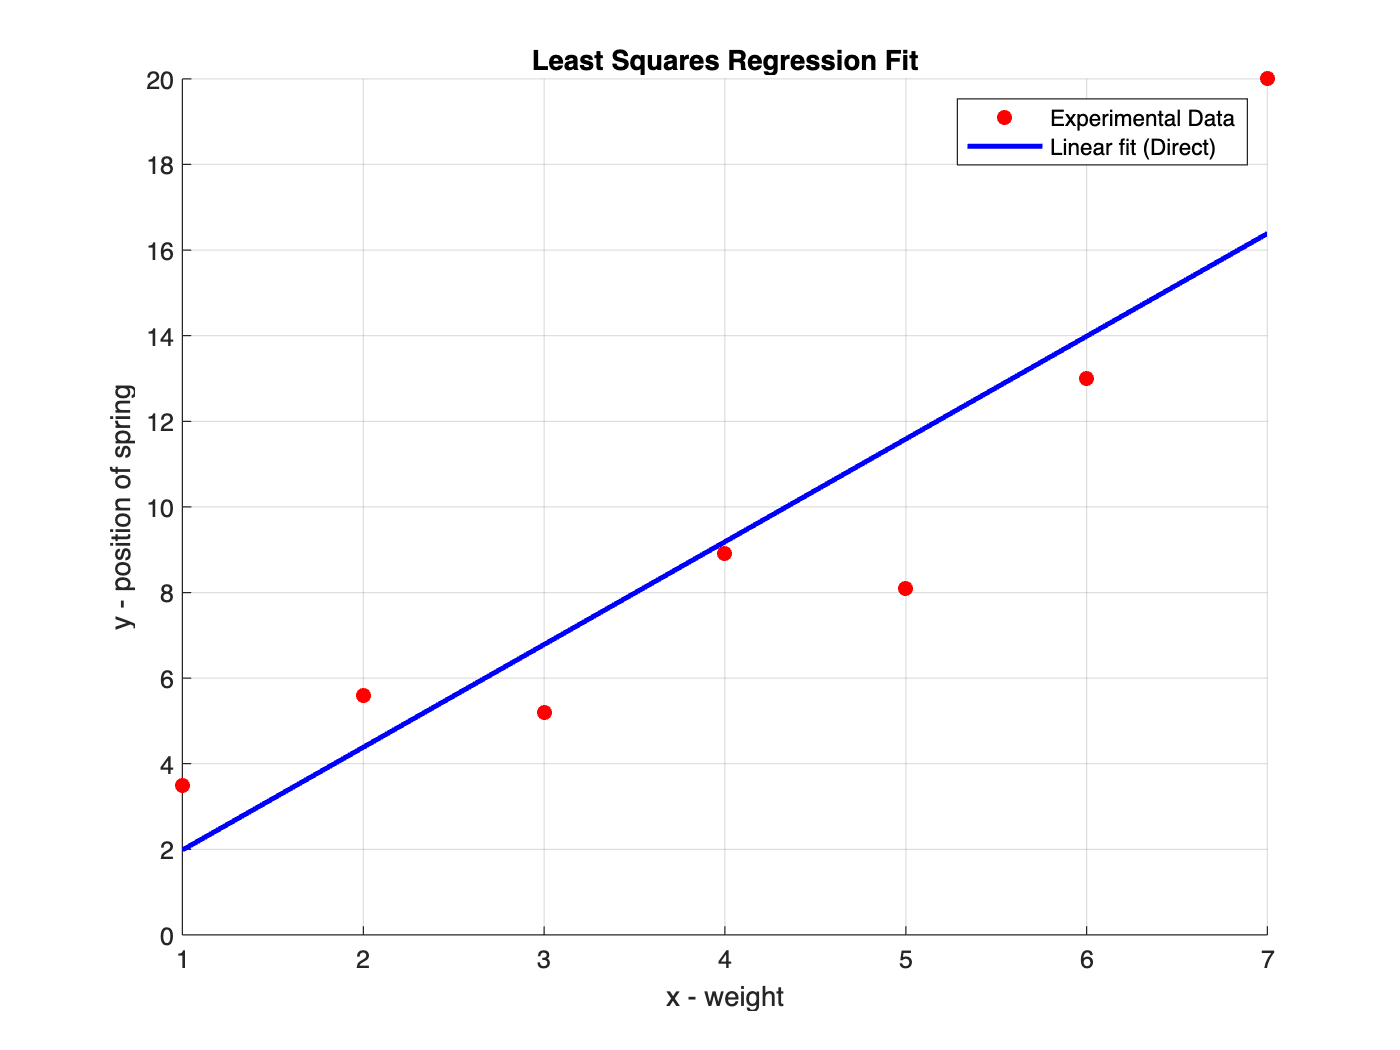

% Option C: Using MATLAB's mldivide (backslash operator)
alpha_lstsq = A \ y; 
disp(['Linear regressor coefficients (using MATLAB LSQ): ', num2str(alpha_lstsq')]);
% Plotting the results
figure;
hold on;
scatter(x, y, 'r', 'filled', 'DisplayName', 'Experimental Data');
plot(x, alpha_direct(1) * x + alpha_direct(2), 'b', 'LineWidth', 2, 'DisplayName', 'Linear fit (Direct)'); % LS fit using Direct method
xlabel('x - weight');
ylabel('y - position of spring');
legend('show');

title('Least Squares Regression Fit');
grid on;
hold off;

## Generalization of the Least Squares Approach

In general, least squares can be applied to fit models other than straight lines, such as polynomials or even nonlinear functions. This section demonstrates fitting more complex models using [`lsqcurvefit`](https://www.mathworks.com/help/optim/ug/lsqcurvefit.html) and `polyfit/ployval` techniques:

`[`[`x`](https://www.mathworks.com/help/optim/ug/lsqcurvefit.html#buuhcjo_sep_shared-x)`,`[`resnorm`](https://www.mathworks.com/help/optim/ug/lsqcurvefit.html#buuhcjo-resnorm)`] ``= lsqcurvefit(`[`fun`](https://www.mathworks.com/help/optim/ug/lsqcurvefit.html#buuhcjo-fun)`,`[`x0`](https://www.mathworks.com/help/optim/ug/lsqcurvefit.html#buuhcjo_sep_shared-x0)`,`[`xdata`](https://www.mathworks.com/help/optim/ug/lsqcurvefit.html#buuhcjo-xdata)`,`[`ydata`](https://www.mathworks.com/help/optim/ug/lsqcurvefit.html#buuhcjo-ydata)`)` starts at `x0` and finds coefficients `x` to best fit the nonlinear function `fun(x,xdata)` to the data `ydata` (in the least-squares sense). `ydata` must be the same size as the vector (or matrix) `F` returned by `fun`. `resnorm`  is the value of the squared 2-norm of the residual at `x`: `sum((fun(x,xdata)-ydata).^2)`.

`[`[`p`](https://www.mathworks.com/help/matlab/ref/polyfit.html#bue6sxq-1-p)`,`[`S`](https://www.mathworks.com/help/matlab/ref/polyfit.html#bue6sxq-1-S)`,`[`mu`](https://www.mathworks.com/help/matlab/ref/polyfit.html#bue6sxq-1-mu)`] = polyfit(`[`x`](https://www.mathworks.com/help/matlab/ref/polyfit.html#bue6sxq-1-x)`,`[`y`](https://www.mathworks.com/help/matlab/ref/polyfit.html#bue6sxq-1-y)`,`[`n`](https://www.mathworks.com/help/matlab/ref/polyfit.html#bue6sxq-1-n)`)` performs `centering` and `scaling` to improve the numerical properties of both the polynomial and the fitting algorithm. This syntax additionally returns `mu`, which is a two-element vector with centering and scaling values. `mu(1) is mean(x)`, and `mu(2) is std(x)`. Using these values, `polyfit` centers `x` at zero and scales it to have unit standard deviation.

`S` - the error estimation structure is used as an input to the `polyval` function to obtain error estimates. `S` contains the following fields:

### **Practical approach to the encoding of the LSQ task in MATLAB**

The Least Squares (LSQ) task involves three key conceptual steps that directly translate to code implementation:

- **Define a Parameterized Model**: Create a mathematical `model` that describes `potential relationship` between the inputs and outputs of the system, with `unknown parameters` that need to be estimated (e.g., linear, polynomial models).

- **Obtain Data**: Gather or generate data that captures the `input-output relationship` of the system. This data will be used to estimate the parameters of the model.

- **Solve the LSQ Problem**: Use an optimization method (like MATLAB’s `lsqcurvefit` or `polyfit`) to minimize the sum of squared residuals between the observed data and model predictions. This yields the parameter estimates that best fit the data.

These steps form the foundation of implementing LSQ fitting in code, guiding the creation of a model, feeding it with data, and solving for the best-fit parameters.

### Example 2: Fitting a sine function using `lsqcurvefit()`

% Define sine function model in a parameterized form wrt b-coefficients
f = @(b,x) b(1) * sin(b(2) * x + b(3)); 

% sampling of data including additive noise
x_data = linspace(0, 2*pi, 10);

b0 =      1     1     1


y_data = 2 * sin(1.5 * x_data + 0.5) + 0.5 * randn(size(x_data));



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


% Initial guess for parameters "b"

b_fit =     2.3093    1.3347    0.8465


b0 = [1, 1, 1] % play with [0.1, 0.1, 0.1]

resnorm = 3.0623

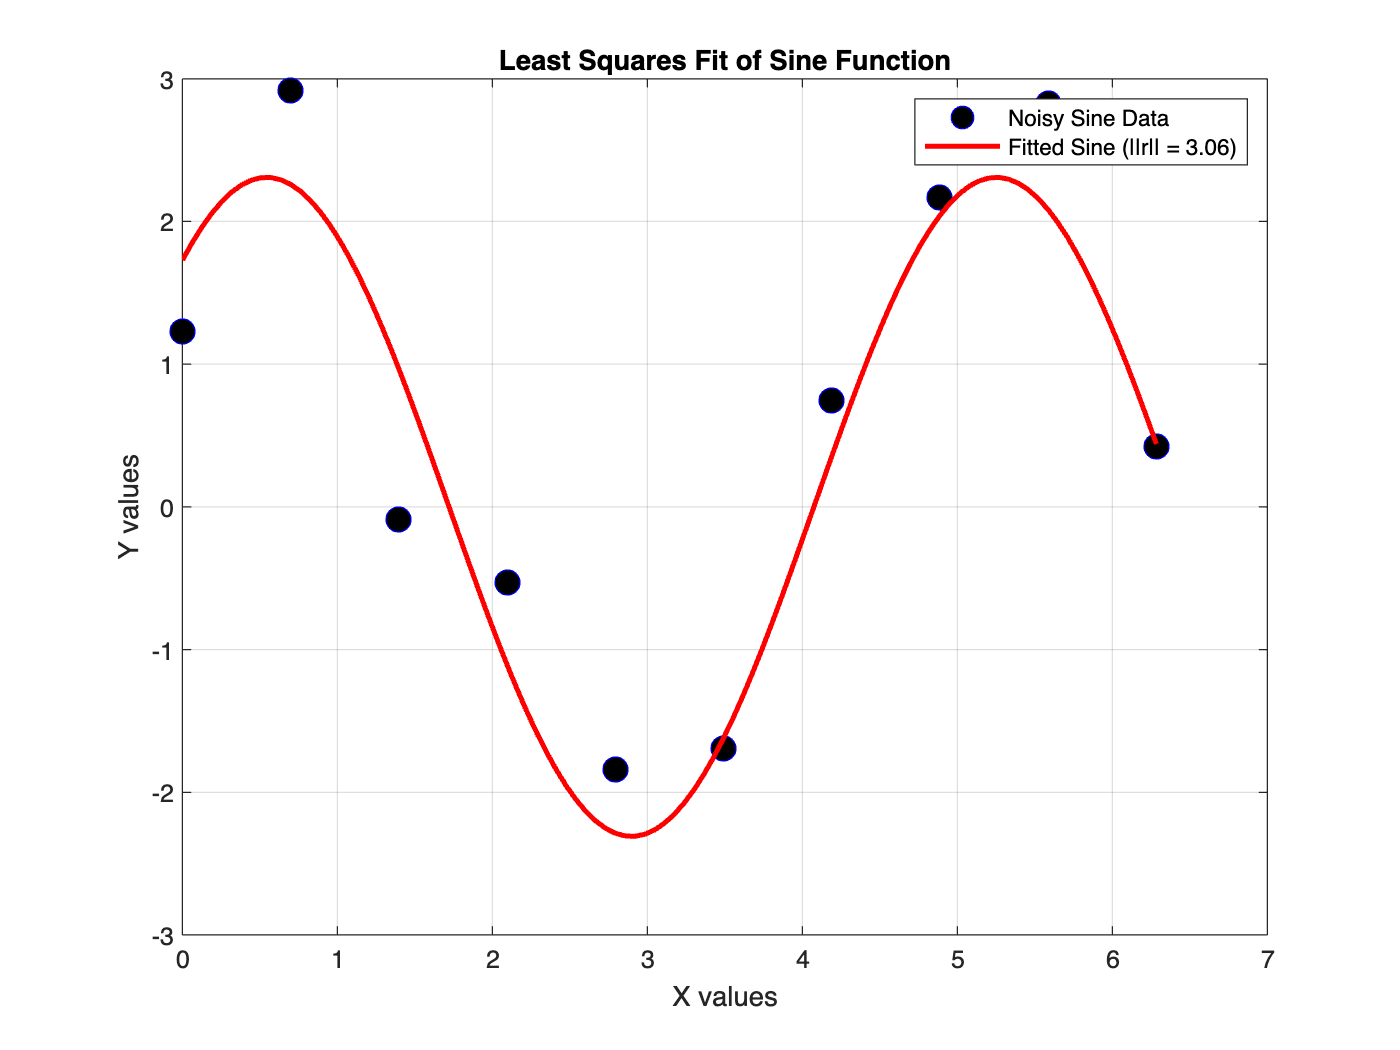

% Solve the LSQ problem
[b_fit, resnorm] = lsqcurvefit(f, b0, x_data, y_data);
b_fit
resnorm
% Plotting the sine fit using as an argument completely different sampling
x_fit = linspace(0, 2*pi, 100);
y_fit_sine = f(b_fit, x_fit);

figure;
plot(x_data, y_data, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'k' , 'DisplayName', 'Noisy Sine Data');
hold on;
plot(x_fit, y_fit_sine, 'r-', 'LineWidth', 2, 'DisplayName', sprintf('Fitted Sine (||r|| = %.2f)', resnorm));
xlabel('X values');

ylabel('Y values');
title('Least Squares Fit of Sine Function');
legend show;
grid on;hold off;

More deatils on the `solver options` and the capabilities of `tuning the LSQ` algorithm can be found [here](https://www.mathworks.com/help/optim/ug/lsqcurvefit.html#buuhcjo-options).

## **Managing LSQ solver options**

Control of the LSQ solver options can be achieved through [options](https://www.mathworks.com/help/optim/ug/lsqcurvefit.html#buuhcjo-options) structure. Some options apply to all algorithms, and others are relevant for particular algorithms. See [Optimization Options Reference](https://www.mathworks.com/help/optim/ug/optimization-options-reference.html) for detailed information.

### **Example 3**: Managing options of ``lsqcurvefit()``solver.

Define a more complex model to both generate the noisy data and to define the "unknown parameterized mode".


$$f(x) = b_3 + e^\frac{b_1\cdot sin( b_2 \cdot x )}{ x}$$



                                        First-order                     Norm of 
 Iteration  Func-count      Resnorm      optimality       Lambda           step
     0           4          17.1883            18.3         0.01
     1           8         0.513409            1.48        0.001       0.748561
     2          12         0.255638           0.112       0.0001       0.203042
     3          16         0.213535           0.131        1e-05       0.218736
     4          20         0.204541          0.0316        1e-06       0.150556
     5          24         0.203866          0.0114        1e-07      0.0535465
     6          28         0.203701         0.00441        1e-08       0.024509
     7          32         0.203676         0.00196        1e-09      0.0100471
     8          36         0.203671        0.000816        1e-10     0.00433034
     9          40         0.203671        0.000349        1e-11     0.00182809
    10          44          0.20367        0.000148  

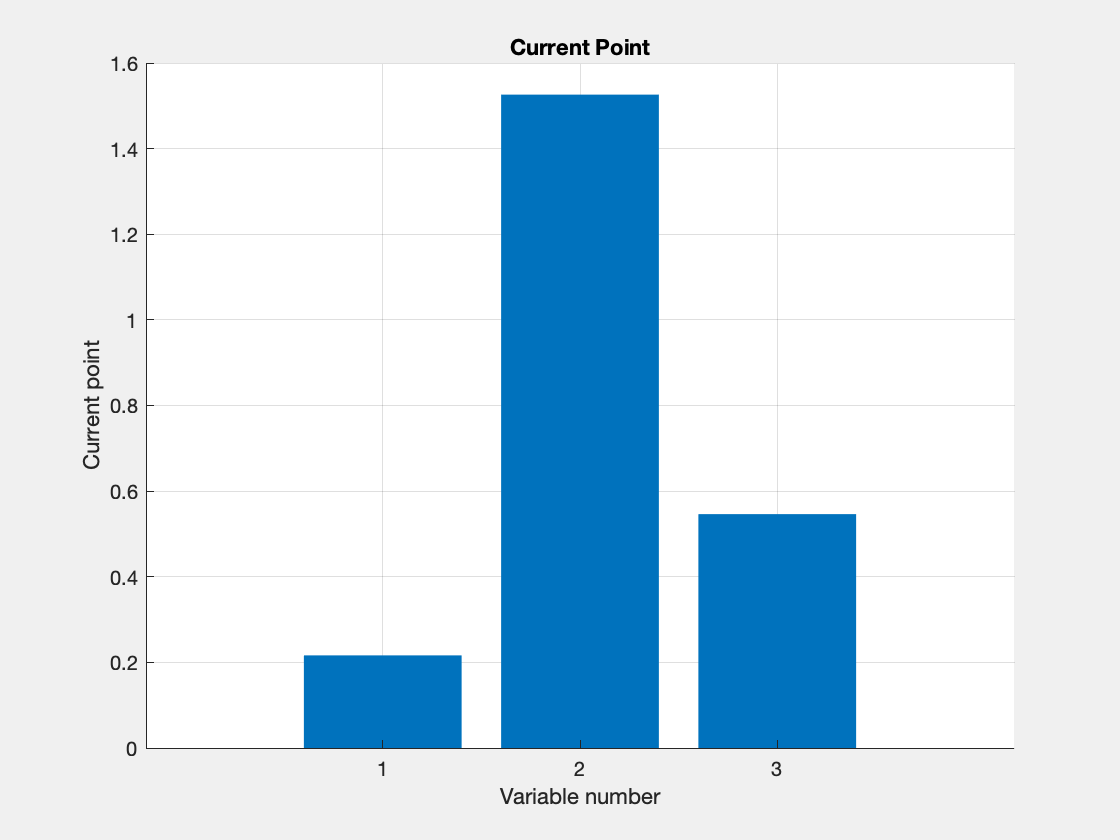

% Define the sine function model
sineModel = @(b, x) exp( b(1) * sin(b(2) * x)./x) + b(3);

% Initial guess for the parameters
initialParams = [1, 1, 1];

% Generate synthetic noisy sine data
x_data = linspace(-2*pi, 2*pi, 20);
y_data = 0.5 + exp( 0.2 * sin(1.5 * x_data)./x_data)+ 0.1 * randn(size(x_data)); 

% Solver options => any of those can be changed or skipped !!!
opts = optimoptions('lsqcurvefit', 'Display', 'iter',...
    'Algorithm','levenberg-marquardt',...
    'MaxFunctionEvaluations',2000,...
    'MaxIterations',10000,...
    'OptimalityTolerance',1e-9,...

    PlotFcn='optimplotx'); 

fitParams =     0.2163    1.5261    0.5463


resnorm = 0.2037

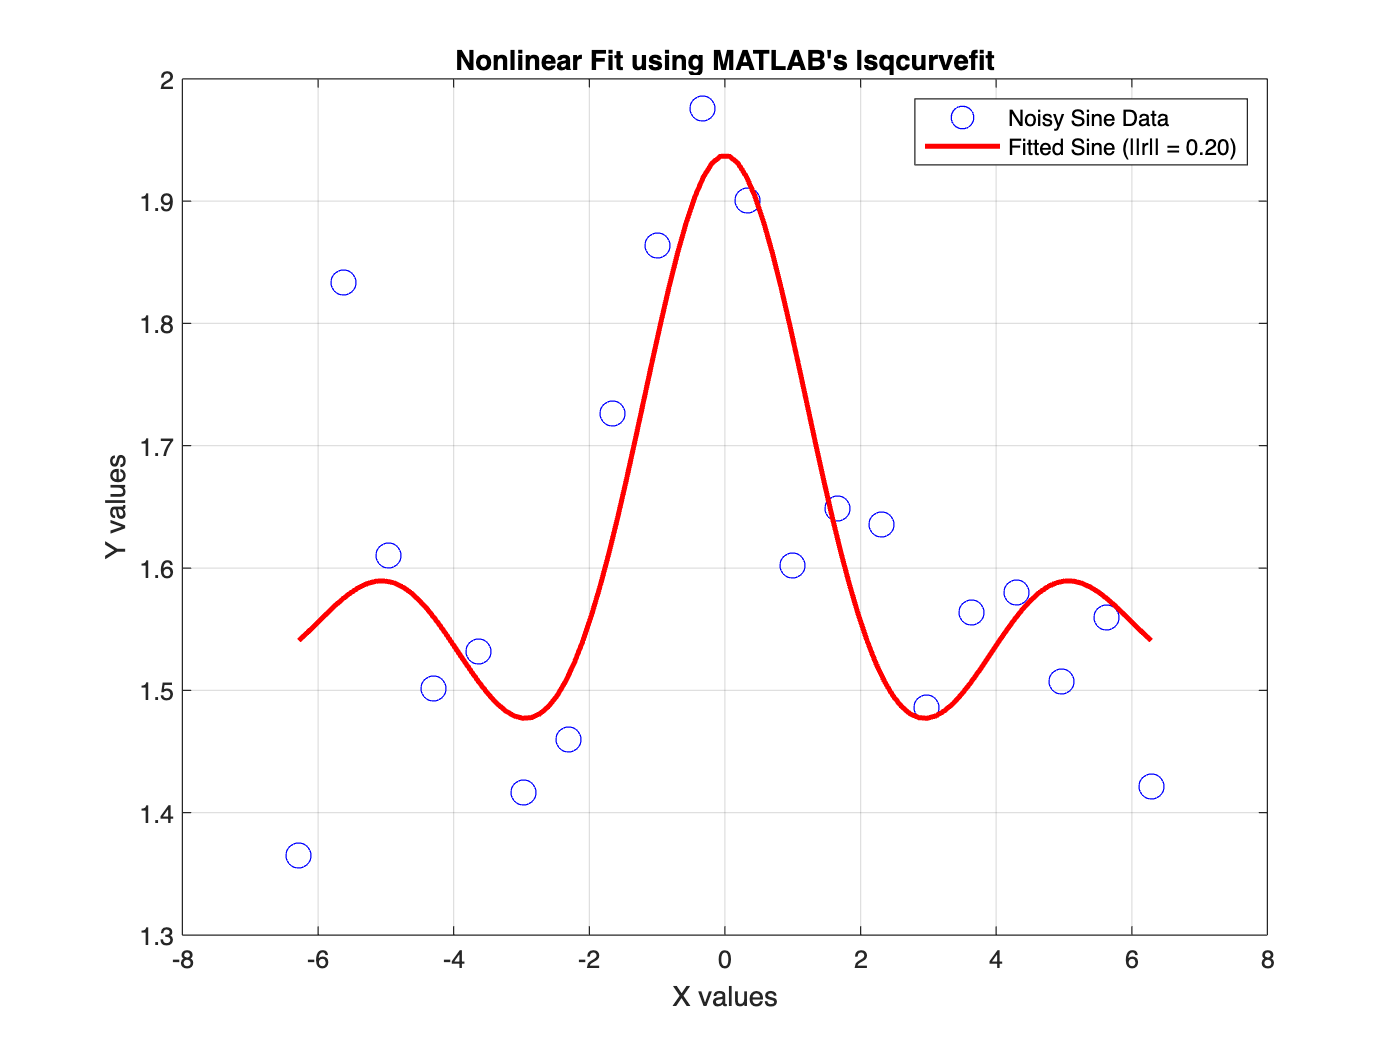

% Fit the sine model to the data using `lsqcurvefit`
[fitParams, resnorm] = lsqcurvefit(sineModel, initialParams, x_data, y_data, [], [], opts);
fitParams
resnorm
% Generate fitted data 
x_fit = linspace(-2*pi, 2*pi, 100);
y_fit_sine = sineModel(fitParams, x_fit);

% Plotting the fitted sine curve
figure;
plot(x_data, y_data, 'bo', 'MarkerSize', 10, 'DisplayName', 'Noisy Sine Data');
hold on;
plot(x_fit, y_fit_sine, 'r-', 'LineWidth', 2, 'DisplayName', sprintf('Fitted Sine (||r|| = %.2f)', resnorm));
xlabel('X values');

ylabel('Y values');
title('Nonlinear Fit using MATLAB''s lsqcurvefit');
legend show;

Fitted Parameters for the Sine Function:


grid on;hold off;

    0.2163    1.5261    0.5463




% Display the fitted parameters
disp('Fitted Parameters for the Sine Function:');
disp(fitParams);

## Summary of Least Square Regression

Least squares regression is a powerful tool for fitting models to data. From linear to non-linear models, MATLAB provides multiple ways to implement least squares. We explored basic linear fits, generalized polynomial fits, and even non-linear approaches using Python's SciPy. The choice of method depends on the complexity of the data and the model. For more sophisticated fits, consider leveraging optimization libraries or advanced numerical techniques.